EENG421 Digital Receiver Project

Description:

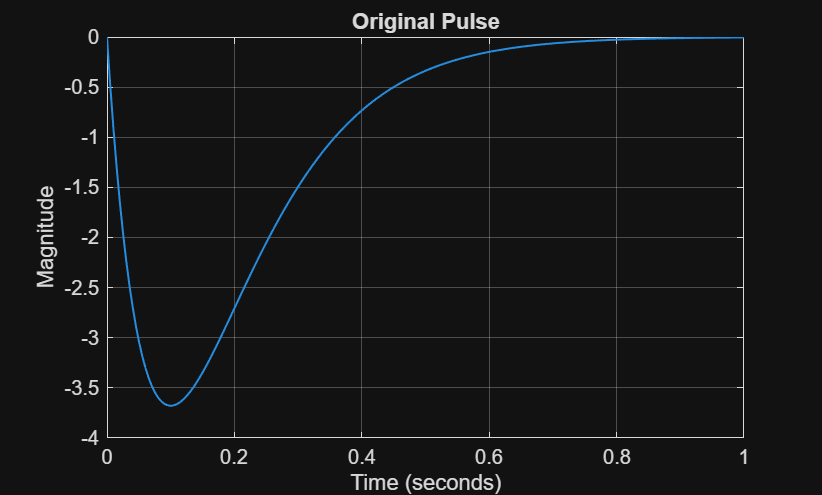

clc;
clear;

matched_filter;

% Sample Plots for One Pulse
% -----------------------------
figure; 
plot(t, p_t, 'LineWidth', 1);
xlabel("Time (seconds)");
ylabel("Magnitude");
title("Original Pulse");
grid on;

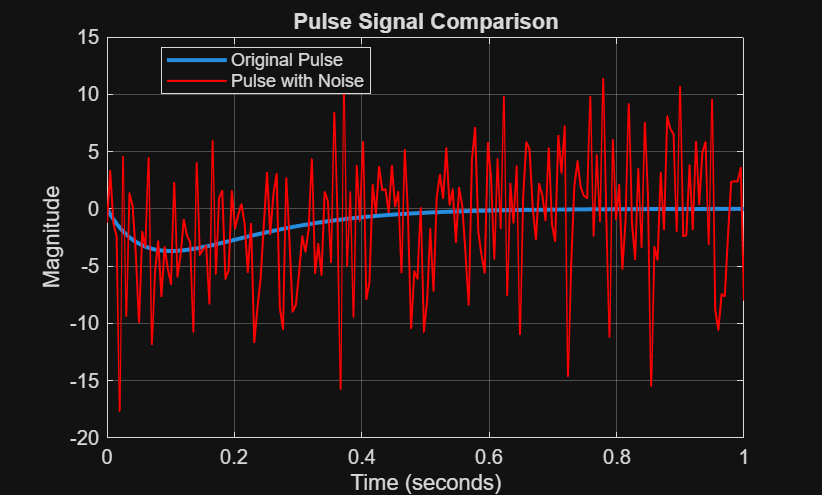


figure; 
plot(t, p_t, 'LineWidth', 2, 'DisplayName', 'Original Pulse');
hold on;
plot(t, y_t, 'LineWidth', 1, 'Color', 'r', 'DisplayName', 'Pulse with Noise');
hold off;

xlabel("Time (seconds)");
ylabel("Magnitude");
title("Pulse Signal Comparison");
legend('show', 'Location', 'best');
grid on;

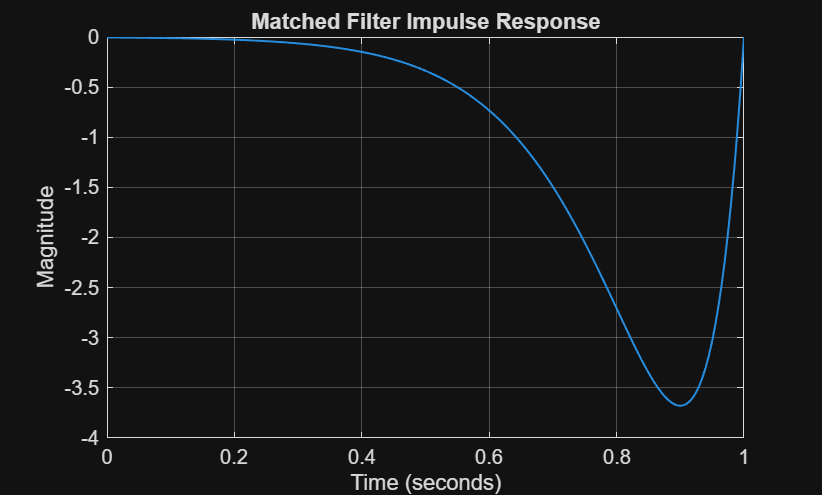


figure; 
plot(t_conv, h_t, 'LineWidth', 1);
xlabel("Time (seconds)");
ylabel("Magnitude");
title("Matched Filter Impulse Response");
grid on;

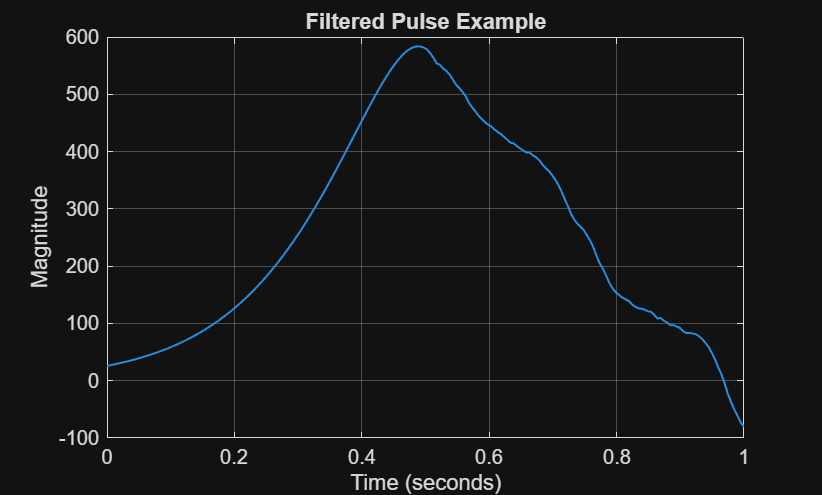


figure; 
plot(t_conv, r_t, 'LineWidth', 1);
xlabel("Time (seconds)");
ylabel("Magnitude");
title("Filtered Pulse Example");
grid on;

Out-Of-Band Energies

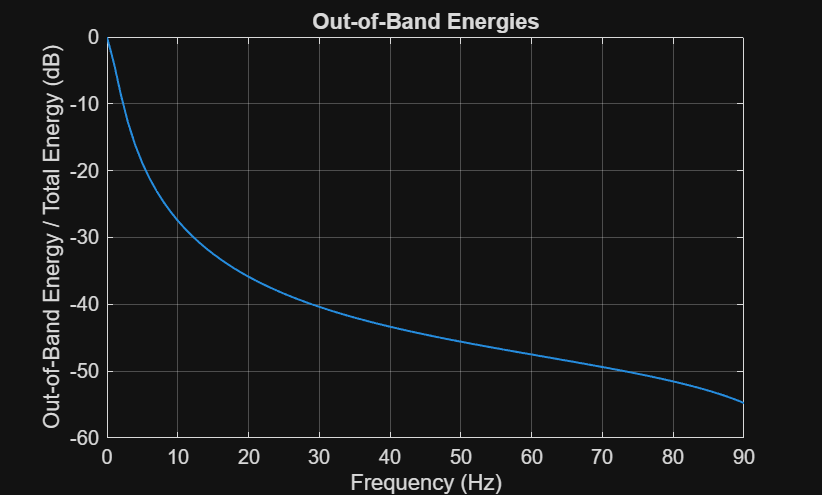

number_of_samples = length(p_t);
frequencies = (0:number_of_samples - 1) * (f_s / number_of_samples);
dt = 1/f_s;

P_f = fft(p_t) * dt;
total_energy = sum(abs(p_t) .^ 2) * dt;
energy_spectral_density = abs(P_f) .^2;
cumulative_energy = cumtrapz(frequencies, energy_spectral_density);

in_band_energy = (2 * cumulative_energy) / total_energy;
out_of_band_energy = 1 - in_band_energy; 
out_of_band_energy_dB = 10 * log10(out_of_band_energy);

figure; 
plot(frequencies, real(out_of_band_energy_dB), 'LineWidth', 1);
xlabel("Frequency (Hz)");
ylabel("Out-of-Band Energy / Total Energy (dB)");
title("Out-of-Band Energies");
xlim([0 90]);
grid on;

Predicting Probability Errors

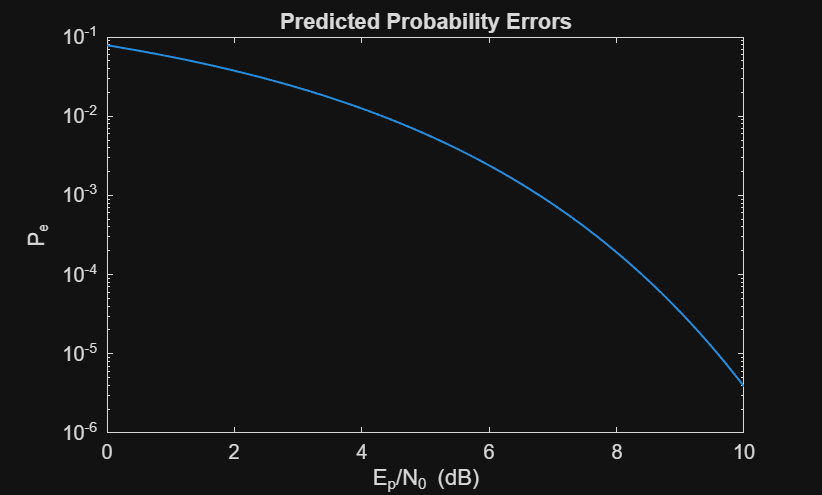

guesses = zeros(1, 1e6);

real_error_probability = zeros(1, length(energy_div_nsd));
predicted_error_probability = zeros(1 , length(energy_div_nsd));
real_incorrect_probabilities = zeros(1, length(energy_div_nsd));
predicted_incorrect_probabilities = zeros(1, length(energy_div_nsd));

% Generate random guesses for the matched filter output
for i = 1:11
    for j = 1:length(guesses)
        current_guess = r_t;
        if current_guess > 0
            guesses(j) = 1;
        else
            guesses(j) = 0;
        end
    end
    
     for j = 1:num_symbols
         if message(j) ~= guesses(j)
            real_incorrect_probabilities(i) = real_incorrect_probabilities(i) + 1;
         end
     end

     predicted_error_probability(i) = qfunc(sqrt(2 * 10 ^(e)))
end
figure; 
plot(energy_nsd_ratios, predicted_error_probability, 'LineWidth', 1);
xlabel('E_p/N_0 (dB)');
ylabel('P_e');
title("Predicted Probability Errors");
yscale('log');
grid off;